## L6: Analiza mowy w dziedzinie czasu

Proszę zaimplementować brakujące funkcje (label, pitchwin) tak, aby ostatecznie uzyskać segmentację sygnału na ciszę, fragmenty dźwięczne i bezdźwięczne. Wszystkie funkcje proszę zaimplementować na końcu dostarczonego notatnika

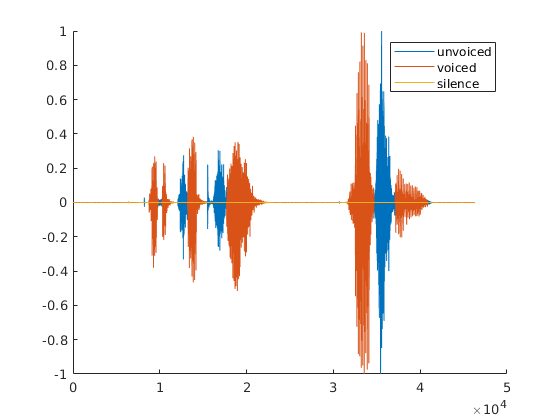

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

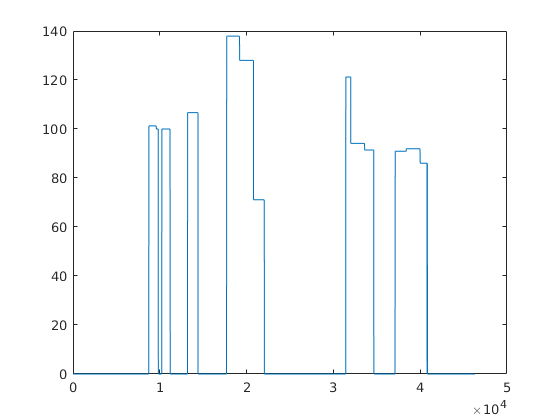


figure;
plot(f0);